clc; close all; clear all; 
load("demoImage.mat");

## Load the data

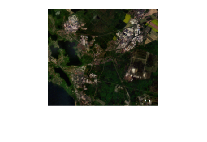

R = 633;
G = 532;
B = 450;

[~, idxR] = min(abs(wavelengths - R));
[~, idxG] = min(abs(wavelengths - G));
[~, idxB] = min(abs(wavelengths - B));

RGBbands    = [idxR, idxG, idxB];

figure;
hcube2       = hypercube(image, wavelengths);
coloredImg2  = colorize(hcube2, "Method", "rgb", "ContrastStretching",true);
imshow(coloredImg2);

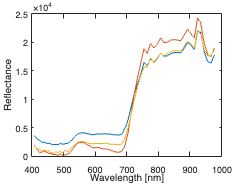

figure; 
plot(wavelengths, squeeze(image(43,83,:)));
hold on;
plot(wavelengths,  squeeze(image(5,33,:)));
plot(wavelengths,  squeeze(image(100,200,:)));
xlabel("Wavelength [nm]");
ylabel("Reflectance");

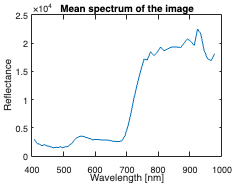

[row, col, d] =  size(image);
spectra2D    = reshape(image, [], d, 1);
meanSpectrum = mean(spectra2D);

figure; 
plot(wavelengths, meanSpectrum);
xlabel("Wavelength [nm]");
ylabel("Reflectance");
title("Mean spectrum of the image");

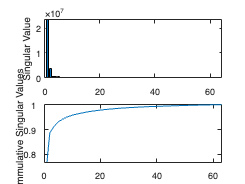

[U, S, V] = svd(spectra2D, "econ");

figure; 
nexttile; 
bar(diag(S));
ylabel("Singular Value")
nexttile;
plot(cumsum(diag(S))/sum(diag(S)));
ylabel("Cummulative Singular Values");

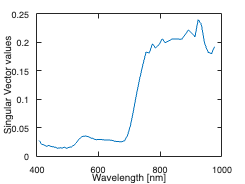

figure; 
plot(wavelengths, -V(:,1));
xlabel("Wavelength [nm]");
ylabel("Singular Vector values");

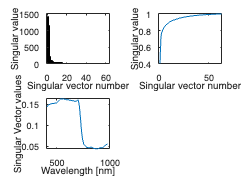

[spectra2Dsc, muX, stdX] = zscore(spectra2D);
[U2, S2, V2] = svd(zscore(spectra2Dsc), "econ");

figure; 
nexttile; 
bar(diag(S2));
xlabel("Singular vector number");
ylabel("Singular value");

nexttile;
plot(cumsum(diag(S2))/sum(diag(S2)));
xlabel("Singular vector number");
ylabel("Singular value");

nexttile;
plot(wavelengths, V2(:,1));
xlabel("Wavelength [nm]");
ylabel("Singular Vector values");

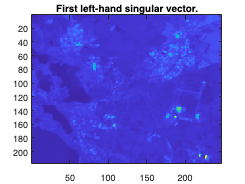

v1 = reshape(U2(:,1), row, col, 1);
figure; 
imagesc(v1);
title("First left-hand singular vector.")

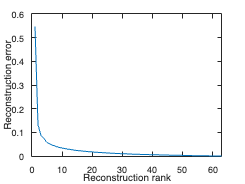

for i = 1:63
    reconstr  = U2(:,1:i) * S2(1:i,1:i) * V2(:,1:i)';
    rmseR(i)  = mean(rmse(spectra2Dsc, reconstr));

    elem = numel(U2(:,1:i)) + numel(V2(:,1:i));
    perc(i) = elem/numel(image);
end

figure;
plot(1:63, rmseR);
ylabel("Reconstruction error");
xlabel("Reconstruction rank");

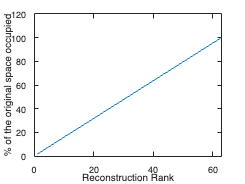


figure;
plot(1:63, perc*100);
xlabel("Reconstruction Rank");
ylabel("% of the original space occupied")

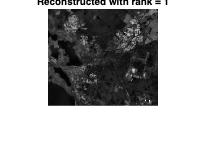

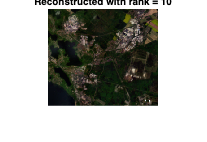

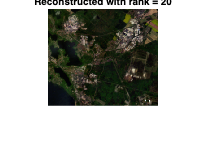

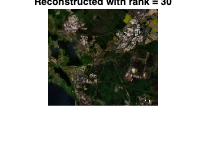



visualize = [1, 10, 20, 30];

for i = 1:length(visualize)
    reconstr = U2(:,1:visualize(i)) * S2(1:visualize(i),1:visualize(i)) * V2(:,1:visualize(i))';

    reconstr = (reconstr + muX) .* stdX;

    reconstr = reshape(reconstr, row, col, d);

    figure;
    hcube2       = hypercube(reconstr, wavelengths);
    coloredImg2  = colorize(hcube2, "Method", "rgb", "ContrastStretching",true);
    imshow(coloredImg2);
    title("Reconstructed with rank = " + string(visualize(i)));
end